% AE6511 Hw6 Problem 5 MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Solving lambda
syms lambda_1(t) lambda_2(t)
X = [lambda_1; lambda_2];
A = [0 1; -1 0];
[l1sol(t),l2sol(t)] = dsolve(diff(X) == A*X);

l1sol(t)

$$ans = C_{1}\,\cos\left(t\right)+C_{2}\,\sin\left(t\right)$$

l2sol(t)

$$ans = C_{2}\,\cos\left(t\right)-C_{1}\,\sin\left(t\right)$$

% Solving x
syms x_1(t) x_2(t) 
u = -l2sol(t)/2;
X = [x_1; x_2];
M = [0 1; -1 0];
g = [0; u];
[x1sol(t),x2sol(t)] = dsolve(diff(X) == M*X + g);

simplify(x1sol(t))

$$ans = C_{3}\,\cos\left(t\right)-0.2500\,C_{2}\,\cos\left(t\right)+C_{4}\,\sin\left(t\right)-0.2500\,C_{1}\,t\,\cos\left(t\right)-0.2500\,C_{2}\,t\,\sin\left(t\right)$$

simplify(x2sol(t))

$$ans = C_{4}\,\cos\left(t\right)-0.2500\,C_{1}\,\cos\left(t\right)-C_{3}\,\sin\left(t\right)-0.2500\,C_{2}\,t\,\cos\left(t\right)+0.2500\,C_{1}\,t\,\sin\left(t\right)$$

clear;

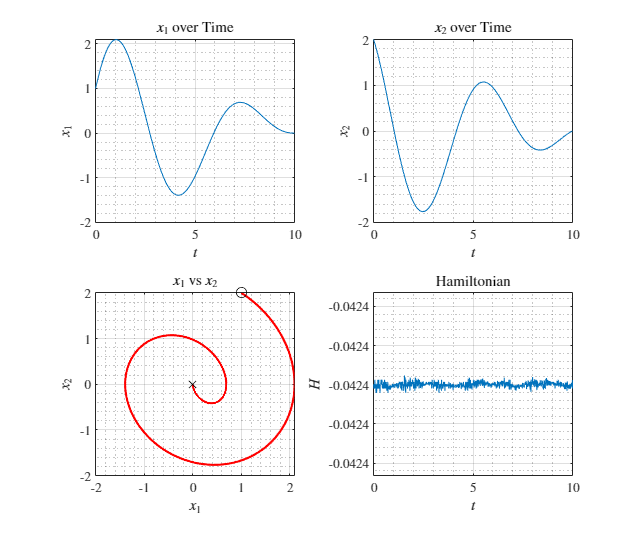

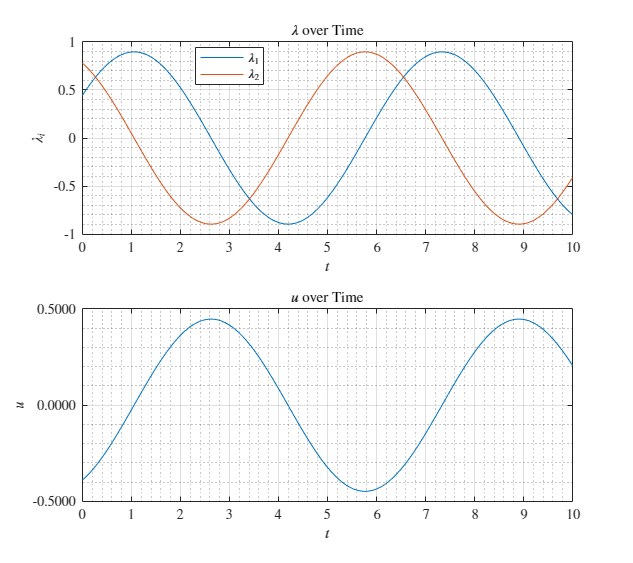

% Then solve for the coefficients
% tf = 10
res1 = coeff_solver(10);
temp = struct2cell(res1);
cs1 = double([temp{:}]).';
CE1 = plotter(10,cs1,"outputs/p5_tf=10.png", ...
    "outputs/p5_control_tf=10.png");

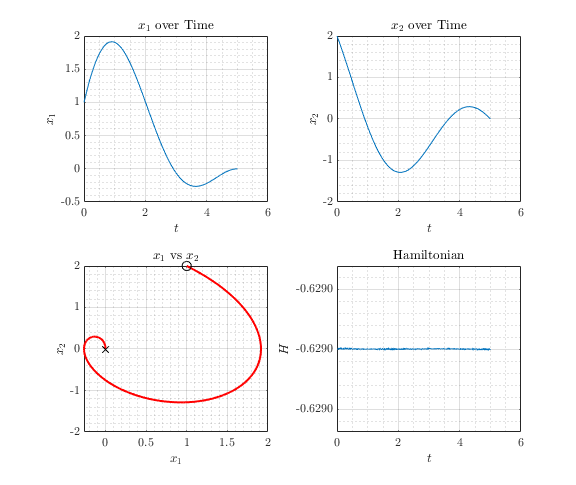

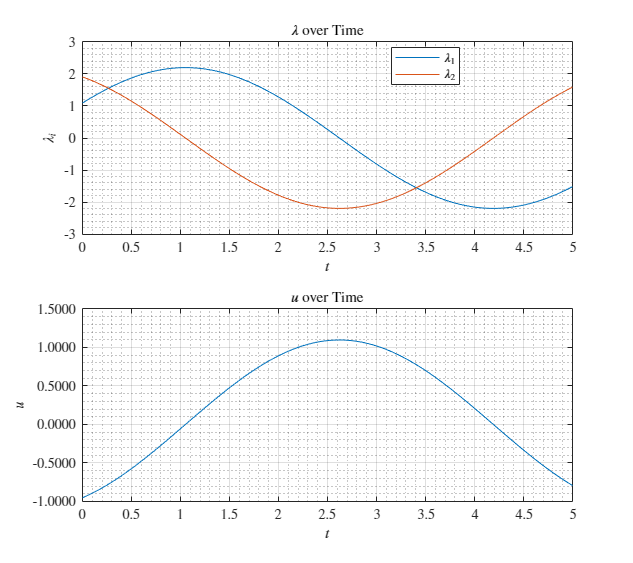

% tf = 5
res2 = coeff_solver(5);
temp = struct2cell(res2);
cs2 = double([temp{:}]).';
CE2 = plotter(5,cs2,"outputs/p5_tf=5.png", ...
    "outputs/p5_control_tf=5.png");

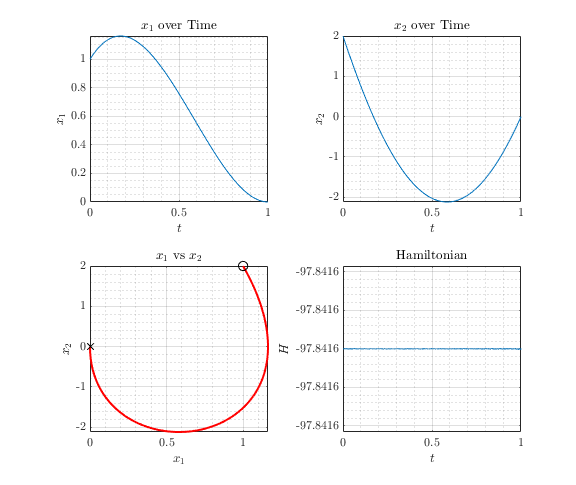

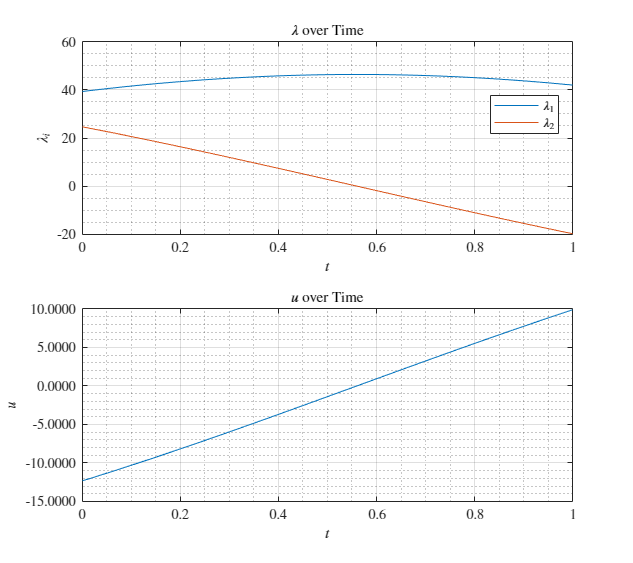

% tf = 1
res3 = coeff_solver(1);
temp = struct2cell(res3);
cs3 = double([temp{:}]).';
CE3 = plotter(1,cs3,"outputs/p5_tf=1.png", ...
    "outputs/p5_control_tf=1.png");

function res = coeff_solver(t_f)
    syms t c_1 c_2 c_3 c_4 
    assume(c_1, 'real'); 
    assume(c_2, 'real'); 
    assume(c_3, 'real'); 
    assume(c_4, 'real'); 

    x1(t) = ((c_3 - c_2/4)*cos(t) + c_4*sin(t) - c_1/4*t*cos(t) ...
        - c_2/4*t*sin(t));
    x2(t) = ((c_4 - c_1/4)*cos(t) - c_3*sin(t) - c_2/4*t*cos(t) ...
        + c_1/4*t*sin(t));
    eqn1 = x1(0) == 1;
    eqn2 = x2(0) == 2;
    eqn3 = x1(t_f) == 0;
    eqn4 = x2(t_f) == 0;
    
    res = solve([eqn1 eqn2 eqn3 eqn4], [c_1 c_2 c_3 c_4]);
end

function CE = plotter(tf,coeffs,fn1,fn2)
    c_1 = coeffs(1); c_2 = coeffs(2);
    c_3 = coeffs(3); c_4 = coeffs(4);
    lambda1 = @(t) c_1*cos(t) + c_2*sin(t);
    lambda2 = @(t) c_2*cos(t) - c_1*sin(t);
    u = @(t) -lambda2(t) / 2;
    u2 = @(t) (-(c_2*cos(t) - c_1*sin(t)) / 2).^2;
    uabs = @(t) abs(-(c_2*cos(t) - c_1*sin(t)) / 2);
    x1 = @(t) ((c_3 - c_2/4)*cos(t) + c_4*sin(t) ...
        - c_1/4*t.*cos(t) - c_2/4*t.*sin(t));
    x2 = @(t) ((c_4 - c_1/4)*cos(t) - c_3*sin(t) ...
        - c_2/4*t.*cos(t) + c_1/4*t.*sin(t));
    H = @(t) (u(t).^2 + lambda1(t) .* x2(t) ...
        + lambda2(t).*(-x1(t) + u(t)));
    
    tspan = linspace(0,tf,1000);
    x1sol = x1(tspan); x2sol = x2(tspan);
    fig = figure("Renderer","painters","Position",[60 60 950 800]);
        % x1 vs t
        subplot(2,2,1)
        plot(tspan, x1sol)
        title('$x_1$ over Time')
        xlabel('$t$')
        ylabel('$x_1$')
        grid on; grid minor; box on;
        % x2 vs t
        subplot(2,2,2)
        plot(tspan, x2sol)
        title('$x_2$ over Time')
        xlabel('$t$')
        ylabel('$x_2$')
        grid on; grid minor; box on;
        % x1 - x2 
        subplot(2,2,3)
        plot(x1sol, x2sol,'-r',LineWidth=1.5)
        hold on;
        plot(x1sol(1),x2sol(1),'ok',MarkerSize=7)
        plot(x1sol(end),x2sol(end),'xk',MarkerSize=7)
        title('$x_1$ vs $x_2$')
        xlabel('$x_1$')
        ylabel('$x_2$')
        grid on; grid minor; box on; hold off;
        % Hamiltonian 
        subplot(2,2,4)
        plot(tspan, H(tspan))
        title('Hamiltonian')
        xlabel('$t$')
        ylabel('$H$')
        ytickformat('%,.4f')
        grid on; grid minor; box on;
    saveas(fig, fn1);

    fig = figure("Renderer","painters","Position",[60 60 900 800]);
        % Plot costates 
        subplot(2,1,1)
        plot(tspan, lambda1(tspan),'DisplayName','$\lambda_1$')
        hold on;
        plot(tspan, lambda2(tspan),'DisplayName','$\lambda_2$')
        title('$\lambda$ over Time')
        xlabel('$t$')
        ylabel('$\lambda_i$')
        legend('Location','best'); grid on; grid minor; box on; hold off;
        % Plot control 
        subplot(2,1,2)
        plot(tspan, u(tspan))
        title('$u$ over Time')
        xlabel('$t$')
        ylabel('$u$')
        ytickformat('%,.4f')
        grid on; grid minor; box on;
    saveas(fig, fn2); 

    % Control Efforts 
    CE.int = sqrt(integral(u2,0,tf));
    CE.abs = integral(uabs,0,tf);
    CE.max = max(uabs(tspan));
end